% Modelisation du robot SCARA Mitsubishi

## PARTIE NON MODIFIABLE

## INITIALISATION

## NE PAS MODIFIER CETTE PARTIE!!!!!!

clc
clear all
close all

% Geometrie du robot
h = 0.8;
L1 = 0.4;
L2 = 0.4;
L3 = 0.2;

% Mesures renvoyees par la camera (position de la piece Ã saisir dans Rc):
xP = 0.5; yP = 0.2; 

% Differentes configurations de test pour les MGD/MGI
Q1 = zeros(1,4);
Q2 = [pi/2 0 0 0];
Q3 = [0 pi/2 0 0];
Q4 = [0 0 -0.5 pi/2];
Q5 = [pi/2 pi/2 -0.5 0];

% FIN DE LA PARTIE NON MODIFIABLE

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Choix de la config de test parmi celles definies au-dessus (ou d'autres Ã votre discretion)
q = Q2;

## A COMPLETER

## SECTION 2.1

	% Utilisation de la fonction drawBM
        drawBM(q);
	% Calcul du MGD et afficher le repere outil
 
        T = mgd(q, h, L1, L2, L3)

T =     0.0000   -1.0000         0    0.0000
    1.0000    0.0000         0    0.8000
         0         0    1.0000    0.8000
         0         0         0    1.0000


        
        % Affichage du repere outil
        drawFrame(T, "MGD", 0.1)
        
	% Ne pas oublier hold on si necessaire pour la superposition des courbes

## SECTION 2.2

	% Calculer ici TOC la matrice de passage homogene entre R0 et Rc
        
        Rc = Rtoc(q, h, L1, L2, L3)

Rc =    -0.0000   -1.0000         0    0.0000
   -1.0000    0.0000         0    1.0000
         0         0   -1.0000    0.8000
         0         0         0    1.0000


        
        % Affichage du repere camera
        drawFrame(Rc, "TOC", 0.1)

	% Determination de la situation de la piece dans R0
        % Donnees: position de la piece dans Rc : (xP, yP, h), orientation : cf. Enonce
	% Deduire la situation de la piece dans R0
        % Afficher la position (X,Y,Z) de la piece dans R0 --> Fonction : plot3(X,Y,Z,'ro'); 
        
        CP = [0.5, 0, h, 1]

CP =     0.5000         0    0.8000    1.0000


        
        Rp = Rpiece(Rc, CP)

Rp =    -1.0000         0         0    0.0000
         0    1.0000         0    0.5000
         0         0   -1.0000         0
         0         0         0    1.0000


        
        % Affichage du repere piece
        drawFrame(Rp, "Piece", 0.2)
  
  	% Calcul du MGI et verification

        [q1, q2] = MGI(L1, L2, Rp(1,4), Rp(2,4))

q1 = 0.7826

q2 = 1.5764


        
        Rp(1,4)

ans = 3.0616e-17

  	% Affichage
        q(1) = q1

q =     0.7826         0         0         0


        q(2) = q2

q =     0.7826    1.5764         0         0


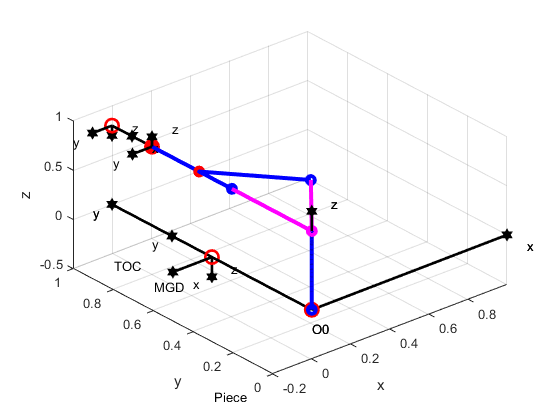

        drawBM(q);